clear, close all

## Punto 1

Dichiarazione delle variabili

dt = .001; %tempo di campionamento
Toss = 100; %tempo di osservazione
t = -Toss/2 :dt: Toss/2; %Asse dei tempi
Nt = length(t); %Numero campioni nel tempo
Nf = 10 *Nt; %Numero di campioni nelle frequenze

Parametri arbitrari

k = 10; 
T = 6;

Genero i grafici

%Calcolo il segnale g(t)
g = cos(pi*k*(t-T/2).^2).*rectpuls((t-T/2)/T); 
g = g';

%Calcolo la trasformata di g(t)
[G,f] = dft(g,t,Nf);

%Trovo l'autocorrelazione di g(t)
Rg = conv(g,flipud(conj(g)), 'same')*dt;

Disegno i grafici

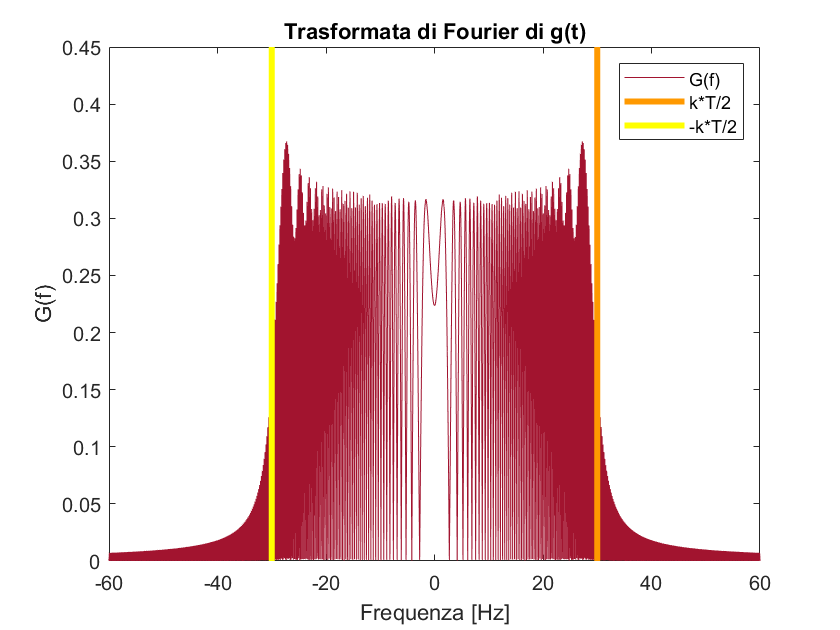

%Trasformata di fourier%
plot(f,abs(G*dt), 'color', [0.6350 0.0780 0.1840]);
hold on
%Traccio due rette costanti che delimitano la banda
h= linspace(0,0.45,20);
estr_pos= (k*T/2)*ones(size(h));  
estr_neg= -(k*T/2)*ones(size(h));  
plot(estr_pos,h, 'color', "#FF9900", 'LineWidth', 3);
hold on 
plot(estr_neg,h, 'y', 'LineWidth', 3);
hold off
title("Trasformata di Fourier di g(t)"), xlabel("Frequenza [Hz]"), ylabel("G(f)");
xlim([-k*T k*T]);
legend("G(f)","k*T/2","-k*T/2");

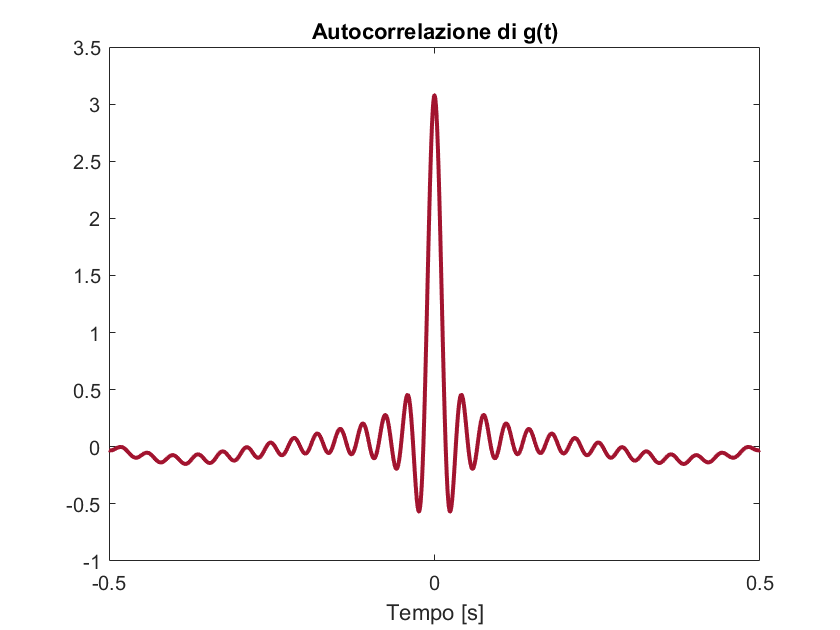


%Autocorrelazione di g(t)
plot(t,Rg, 'color', [0.6350 0.0780 0.1840], 'LineWidth', 2);
title("Autocorrelazione di g(t)"), xlabel("Tempo [s]");
xlim([-0.5 0.5]);

Calcolo il picco di Rg teoricamente e sperimentalmente

%Calcolo l'energia del segnale g(t)
Eg = sum(abs(g.^2),1)*dt

Eg = 3.0791


%Calcolo il massimo e il punto di massimo Rg 
[Max_Rg,n_max] = max(Rg);
Max_Rg %Massima ampiezza di Rg

Max_Rg = 3.0791

posizione_max = t(n_max) %Punto di Massimo di Rg

posizione_max = 0

## Punto 2

Dichiarazione delle variabili

dt = .1; 
T = 100;
t = 0:dt:T;
B = 1;
Nt = length(t);
sigmaw = 5;

Calcolo k

k = B/T; % Ricavo k = B/T

Valore di Tau scelto

tau = 10;

Genero i segnali

%Genero il segnale g(t)
g = cos(pi*k*(t-T/2).^2).*rectpuls((t-T/2)/T);
g = g';
%Genero il rumore w(t) gaussiano bianco
w = sigmaw*randn(1,Nt);
%Genero il seganle x1 senza rumore
x1 = cos(pi*k*(t-tau-T/2).^2).*rectpuls((t-tau-T/2)/T);
%Genero il seganle x1 con il rumore
x1_noise = x1 + w;

%Calcolo l'autocorrelazione di g(t)
Rg = conv(g,flipud(conj(g)),'same')*dt;
%Calcolo la crosscorrelazione fra x1(t) e g(t)
Rx1g = conv(x1,flipud(conj(g)),'same')*dt;
%Calcolo la crosscorrelazione disturbata fra x1(t) e g(t)
Rx1g_noise = conv(x1_noise,flipud(conj(g)),'same')*dt;

Calcolo il Rapporto Segnale-Rumore del segnale x1_noise

%Calcolo la potenza del segnale g(t)
Pg = sum(abs(g.^2),1)*dt/T

Pg = 0.5250


%Calcolo il rapporto Segnale-Rumore
SNR = Pg/(sigmaw^2)

SNR = 0.0210

SNRdB = 10*log10(SNR)

SNRdB = -16.7778

Disegno e confronto i grafici

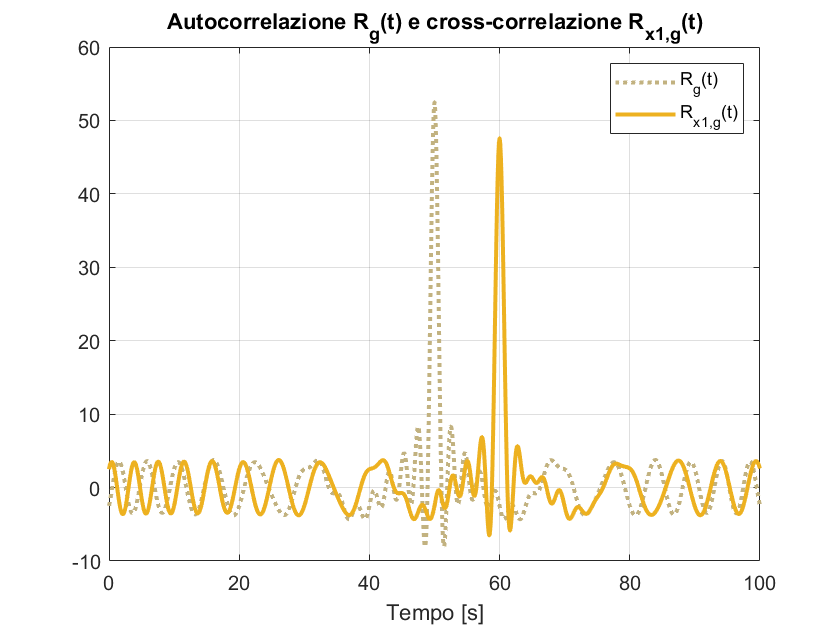

%Confronto l'autocorrelazione con la crosscorrelazione
plot(t,Rg,'color', '#C2B280', "LineStyle",":","LineWidth",2);
hold on
plot(t,Rx1g, 'Color', [0.9290 0.6940 0.1250], "LineWidth", 2);
hold off
title("Autocorrelazione R_g(t) e cross-correlazione R_x_1_,_g(t)"), xlabel("Tempo [s]");
legend("R_g(t)","R_x_1_,_g(t)");
grid on;

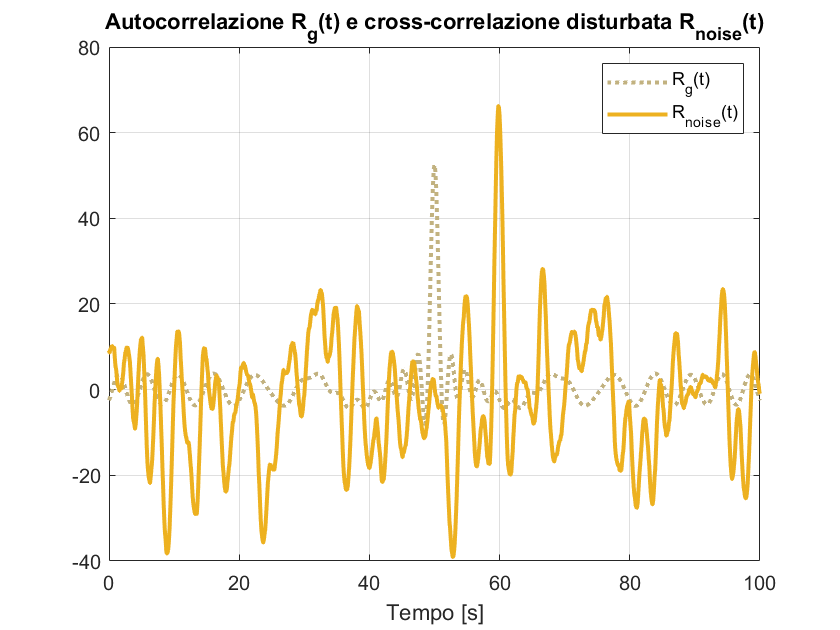


%Confronto La Cross correlazione ideale con quella disturbata
plot(t,Rg,'color', '#C2B280', "LineStyle",":","LineWidth",2);
hold on
plot(t,Rx1g_noise, 'color', [0.9290 0.6940 0.1250], "LineWidth", 2);
hold off
title("Autocorrelazione R_g(t) e cross-correlazione disturbata R_n_o_i_s_e(t)"), xlabel("Tempo [s]");
legend("R_g(t)","R_n_o_i_s_e(t)");
grid on;

Calcolo tau e l'errore nel ritardo

[~,tmax_Rg] = max(Rg);
tmax_Rg = t(tmax_Rg);%punto di massimo dell'autocorrelazione di g(t)
[~, pmax_Rx1g] = max(Rx1g); 
pmax_Rx1g = t(pmax_Rx1g); %punto di massimo della cross ideale
[~, pmax_Rnoise] = max(Rx1g_noise);
pmax_Rnoise = t(pmax_Rnoise); %punto di massimo della cross con rumore

%Calcolo tau come distanza fra i picchi 
%%Caso ideale%%
tau_id = pmax_Rx1g - tmax_Rg

tau_id = 10

%%Caso Reale%%
tau_noise = pmax_Rnoise - tmax_Rg

tau_noise = 9.8000


%Calcolo l'errore percentuale di misura di tau
tau_err = (abs(pmax_Rnoise-pmax_Rx1g)/tau)*100

tau_err = 2.0000

## Punto 3

Dichiarazione delle variabili

sigmaw = 3;
[x1,x2,par] = mod_1(sigmaw);

T = par.Tg;
t = par.tax;
dt = t(2)-t(1);
k = par.Bg/par.Tg;
Nt = length(t);

Generazione dei segnali

%Genero il segnale g(t)
g = cos(pi*k*(t-T/2).^2).*rectpuls((t-T/2)/T);
g = g';
%Genero il segnale x
x = x1 + x2;

%Calcolo l'autocorrelazione di g(t)
Rg = conv(g,flipud(conj(g)),'same')*dt;
%Calcolo la cross-correlazione fra x(t) e g(t)
Rxg = conv(x,flipud(conj(g)),'same')*dt;

Disegno i grafici

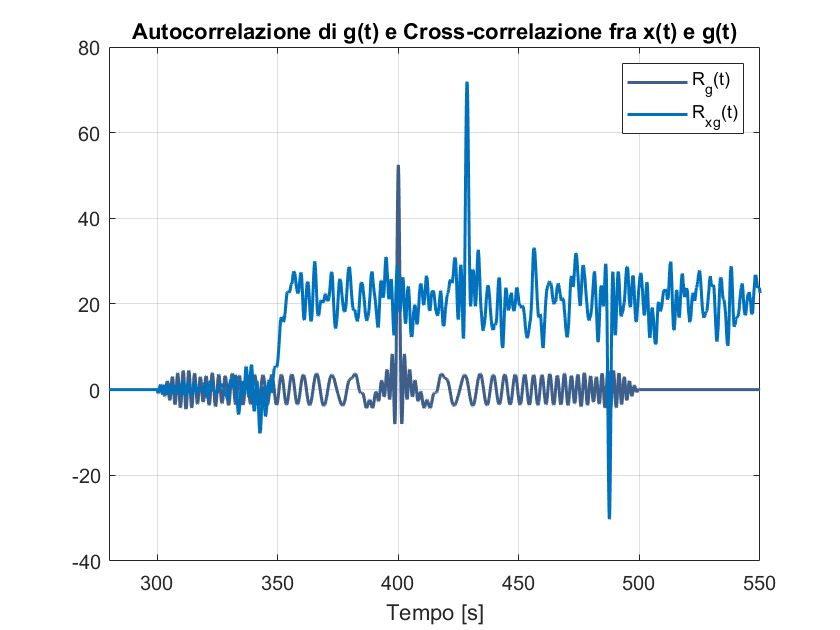

plot(t, Rg, 'color', '#3E5F8A',"LineWidth",1.5);
hold on
plot(t, Rxg, 'color', '#0072BD',"LineWidth",1.5);
hold off
title("Autocorrelazione di g(t) e Cross-correlazione fra x(t) e g(t)"), xlabel("Tempo [s]"), xlim([280 550]);
grid on;
legend("R_g(t)","R_x_g(t)");

Calcolo R1 ed R2

[~,tmax_Rg] = max(Rg);
tmax_Rg = t(tmax_Rg);%punto di massimo dell'autocorrelazione di g(t)

[~, pmax_Rxg] = max(Rxg);
pmax_Rxg = t(pmax_Rxg);%punto di massimo della cross-correlazione Rxg

[~, pmin_Rxg] = min(Rxg);
pmin_Rxg = t(pmin_Rxg);%punto di minimo della crosscorrelazione Rxg

R1 = pmax_Rxg - tmax_Rg %Calcolo R1

R1 = 28.5000

R2 = pmin_Rxg - tmax_Rg %Calcolo R2

R2 = 87.5000

Trovo la posizione (x0,y0)

x0 = abs((R1^2 - R2^2 + 10000)/200)

x0 = 15.7800

y0 = abs(sqrt(R1^2 - x0^2))

y0 = 23.7327

Confronto i dati calcolati con i dati forniti dalla funzione mod_1

%Calcolo l'accuratezza della posizione [x0,y0]
err_x = abs(x0 - par.P(1))

err_x = 0.0853

err_y = abs(y0 - par.P(2))

err_y = 0.0127

## Punto 4

Assegno i valori ad opt

opt_0 = 0;%Poco rumore
opt_5 = 5;%Rumore con sigma = 5
opt_7 = 7;%Rumore con sigma = 7

Dichiarazione delle variabili

[x,par] = mod_2(opt_0);
[x5,~] = mod_2(opt_5);
[x7,~] = mod_2(opt_7);

T = par.Tg;
t = par.tax;
dt = t(2)-t(1);
k = par.Bg/par.Tg;

%Definisco 3 matrici per i 3 valori diversi di opt scelti
out_0 = zeros(150,150);
out_5 = zeros(150,150);
out_7 = zeros(150,150);

Calcolo dei segnali

%Genero il segnale g(t)
g = cos(pi*k*(t-T/2).^2).*rectpuls((t-T/2)/T);
g = g';

%Calcolo l'autocorrelazione di g(t)
Rg = conv(g,flipud(conj(g)),'same')*dt;

[~,tmax_Rg] = max(Rg);
tmax_Rg = t(tmax_Rg);%punto di massimo dell'autocorrelazione di g(t)

Calcolo il percorso per il caso opt = 0

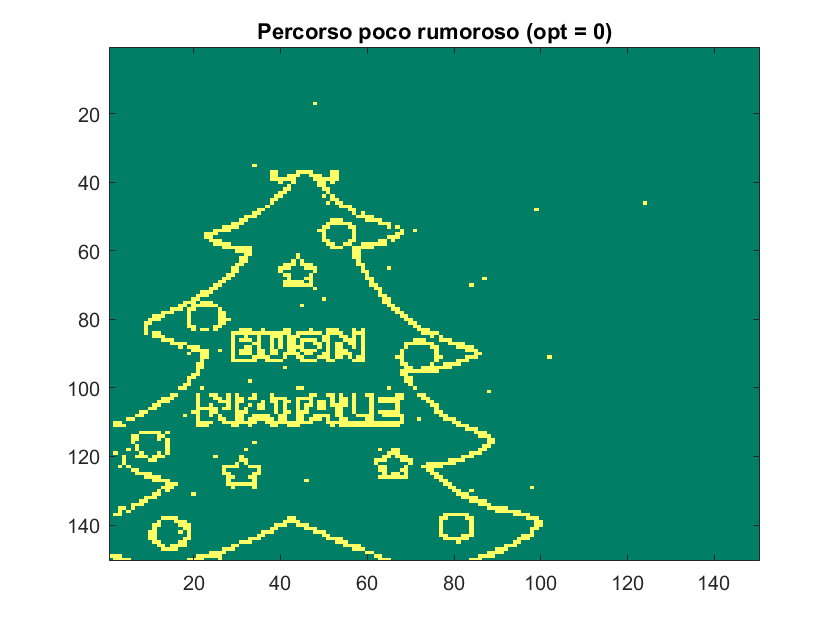

for i = 1 : size(x,1)
    
    %Calcolo le cross-correlazioni con g(t) dei segnali x, x5,x7
    Rx = conv(x(i,:),flipud(conj(g)), "same")*dt;
    
    %Calcolo R1 e R2
    [~, max_Rx] = max(Rx);
    max_Rx = t(max_Rx);
    [~, min_Rx] = min(Rx);
    min_Rx = t(min_Rx);
    
    R1 = max_Rx - tmax_Rg;
    R2 = min_Rx - tmax_Rg;
    
    %Calcolo le coordinate
    x0 = abs((R1^2 - R2^2 +10000)/200);
    y0 = abs(sqrt(R1^2 - x0^2));
    
    %Inserisco 1 nella posizione calcolata
    if (round(x0)>0 && round(x0)<150) && (round(y0)>0 && round(y0)<150)
    out_0(round(x0), round(y0)) = 1;
    end
end

%Disegno la matrice come immagine
out_0 = flipud(out_0);
imagesc(out_0);
title("Percorso poco rumoroso (opt = 0)");
colormap summer;

Calcolo il percorso per il caso opt = 5

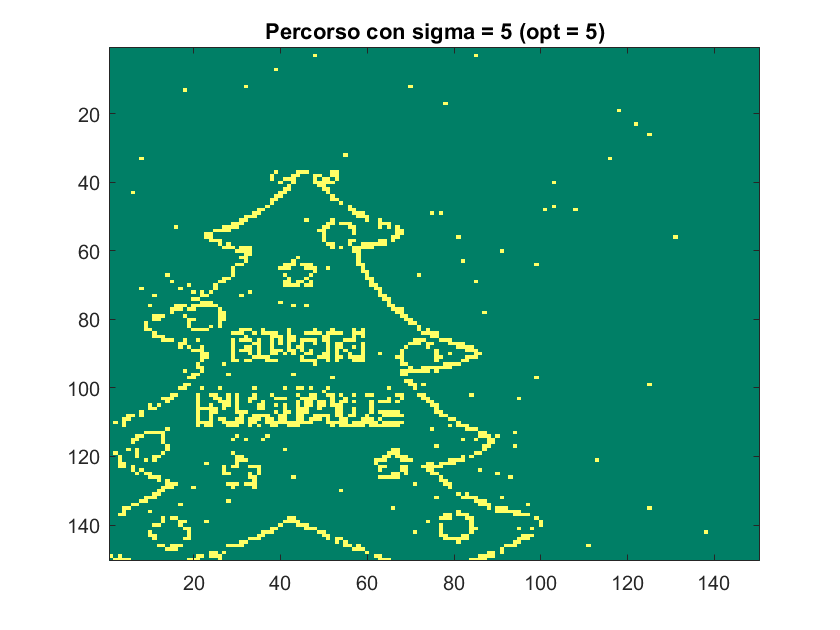

for i = 1 : size(x5,1)
    
    %Calcolo le cross-correlazioni con g(t) dei segnali x, x5,x7
    Rx = conv(x5(i,:),flipud(conj(g)), "same")*dt;
    
    %Calcolo R1 e R2
    [~, max_Rx] = max(Rx);
    max_Rx = t(max_Rx);
    [~, min_Rx] = min(Rx);
    min_Rx = t(min_Rx);
    
    R1 = max_Rx - tmax_Rg;
    R2 = min_Rx - tmax_Rg;
    
    %Calcolo le coordinate
    x0 = abs((R1^2 - R2^2 +10000)/200);
    y0 = abs(sqrt(R1^2 - x0^2));
    
    %Inserisco 1 nella posizione calcolata
    if (round(x0)>0 && round(x0)<150) && (round(y0)>0 && round(y0)<150)
    out_5(round(x0), round(y0)) = 1;
    end
end

%Disegno la matrice come immagine
out_5 = flipud(out_5);
imagesc(out_5);
title("Percorso con sigma = 5 (opt = 5)");
colormap summer;

Calcolo il percorso per il caso opt = 7

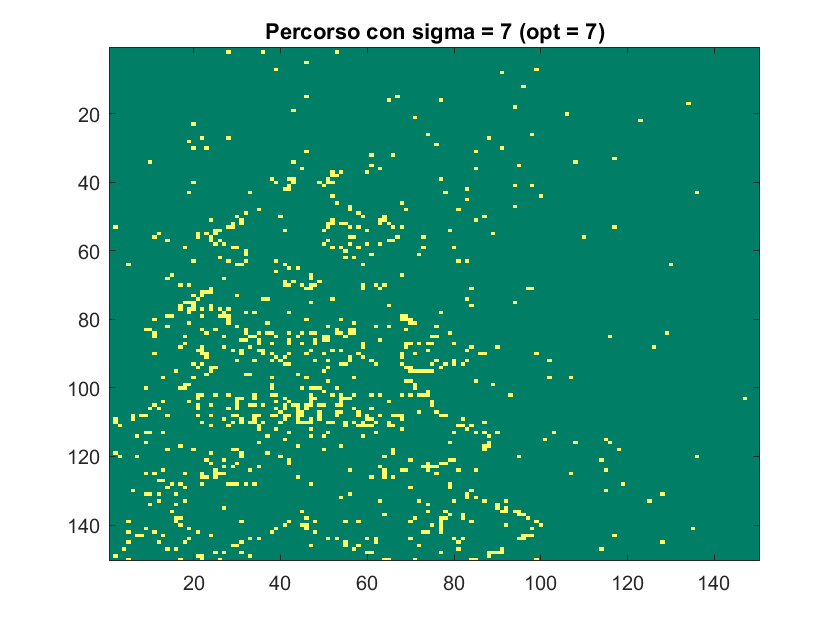

for i = 1 : size(x7,1)
    
    %Calcolo le cross-correlazioni con g(t) dei segnali x, x5,x7
    Rx = conv(x7(i,:),flipud(conj(g)), "same")*dt;
    
    %Calcolo R1 e R2
    [~, max_Rx] = max(Rx);
    max_Rx = t(max_Rx);
    [~, min_Rx] = min(Rx);
    min_Rx = t(min_Rx);
    
    R1 = max_Rx - tmax_Rg;
    R2 = min_Rx - tmax_Rg;
    
    %Calcolo le coordinate
    x0 = abs((R1^2 - R2^2 +10000)/200);
    y0 = abs(sqrt(R1^2 - x0^2));
    
    %Inserisco 1 nella posizione calcolata
    if (round(x0)>0 && round(x0)<150) && (round(y0)>0 && round(y0)<150)
    out_7(round(x0), round(y0)) = 1;
    end
end

%Disegno la matrice come immagine
out_7 = flipud(out_7);
imagesc(out_7);
title("Percorso con sigma = 7 (opt = 7)");
colormap summer;

Conto le false misure

fm_5 = 0;
fm_7 = 0;
for n = 1 : 150
    for m = 1 : 150
        if out_5(n,m) == 1 && out_0(n,m) == 0
            fm_5 = fm_5 + 1;
        end
        if out_7(n,m) == 1 && out_0(n,m) == 0
            fm_7 = fm_7 + 1;
        
        end
    end
end

false_misure_per_sigma5 = fm_5

false_misure_per_sigma5 = 172

false_misure_per_sigma7 = fm_7

false_misure_per_sigma7 = 385